# Examples for 'adaptive.m': an utility for adaptive function evaluation

Adaptively evaluate a function on a given range. There are different methods which can be used for choosing where to add new data points. The default method  provided by 'adaptive.m' is to add more points near the sharp corners, which are found by considering the triangles formed by triplets of successive points and measuring the central angle.

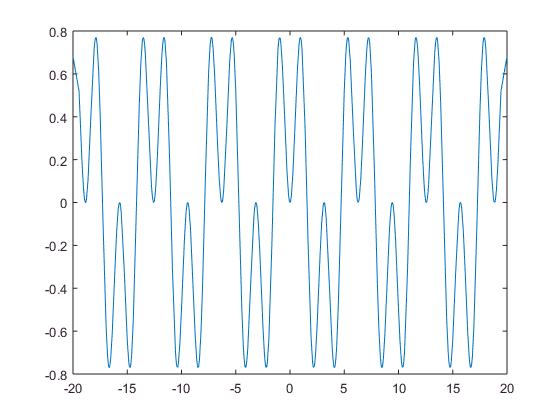

[xi, yi] = adaptive(@(x) sin(x)*sin(2*x), [-20,20]);
plot(xi, yi);

More control can be achieved by explicitly specifying which method to use for the adaptive evaluation process. The option 'minAngle' can be useful for adding more points near the peaks of the function.

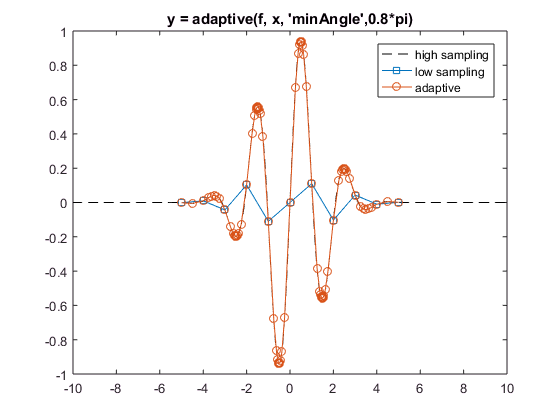

x = -5:5;
f = @(x) exp(-x.^2/4).*sin(3*x);
y = adaptive(f, x, 'minAngle',0.8*pi);
% for test-purpose also evaluate the function directly
x2 = -10:0.01:10;
y2 = f(x2);
figure(1); plot(x2,f(x2),'k--',x,f(x),'s-',y(:,1),y(:,2),'o-');
legend('high sampling','low sampling','adaptive')
title('y = adaptive(f, x, ''minAngle'',0.8*pi)')

Refine a function near sharp corners, but do not split segments which are already shorter than 'minLength'.

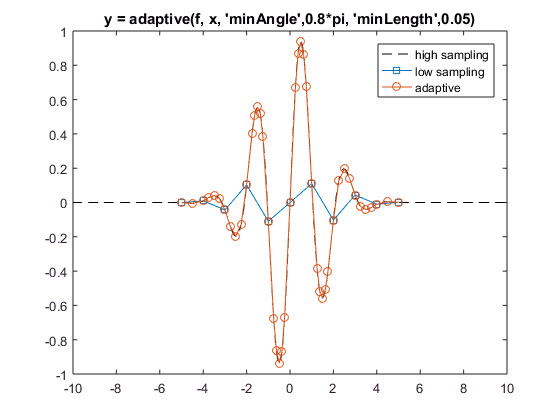

y = adaptive(f, x, 'minAngle',0.8*pi, 'minLength',0.05);
figure(2); plot(x2,y2,'k--',x,f(x),'s-',y(:,1),y(:,2),'o-');
legend('high sampling','low sampling','adaptive')
title('y = adaptive(f, x, ''minAngle'',0.8*pi, ''minLength'',0.05)');

Refine a function until the areas of the triangles formed by triplets of successive points are smaller than 'maxArea'.

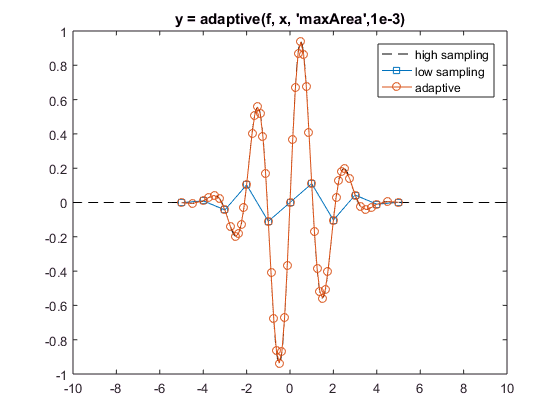

y = adaptive(f, x, 'maxArea',1e-3);
figure(3); plot(x2,y2,'k--',x,f(x),'s-',y(:,1),y(:,2),'o-');
legend('high sampling','low sampling','adaptive')
title('y = adaptive(f, x, ''maxArea'',1e-3)')

Refine a function until the segments formed by pairs of successive points are shorter than 'maxLength'.

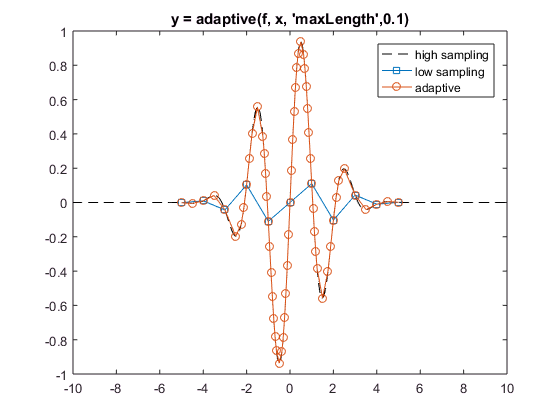

y = adaptive(f, x, 'maxLength',0.1);
figure(4); plot(x2,y2,'k--',x,f(x),'s-',y(:,1),y(:,2),'o-');
legend('high sampling','low sampling','adaptive')
title('y = adaptive(f, x, ''maxLength'',0.1)');